% Limpiando el workspace
clear

% Cargamos los datos de los experimentos
M1_chirp = readmatrix('Experimento_M1_chirp.csv', "Delimiter", ",", "DecimalSeparator", ".");
M1_steps = readmatrix('Experimento_M1_steps.csv', "Delimiter", ",", "DecimalSeparator", ".");
M2_chirp = readmatrix('Experimento_M2_chirp.csv', "Delimiter", ",", "DecimalSeparator", ".");
M2_steps = readmatrix('Experimento_M2_steps.csv', "Delimiter", ",", "DecimalSeparator", ".");
M3_chirp = readmatrix('Experimento_M3_chirp.csv', "Delimiter", ",", "DecimalSeparator", ".");
M3_steps = readmatrix('Experimento_M3_steps.csv', "Delimiter", ",", "DecimalSeparator", ".");
M4_chirp = readmatrix('Experimento_M4_chirp.csv', "Delimiter", ",", "DecimalSeparator", ".");
M4_steps = readmatrix('Experimento_M4_steps.csv', "Delimiter", ",", "DecimalSeparator", ".");

% Unimos los experimentos en un cell array, ya que los experimentos no
% tienen la misma duración y no se pueden agrupar en una matriz
M_chirp = {M1_chirp, M2_chirp, M3_chirp, M4_chirp};
M_steps = {M1_steps, M2_steps, M3_steps, M4_steps};

% En la entrada al motor se asume que se aplica un acción proporcional al
% voltaje de la fuente, por ello, extraemos el voltaje nominal
% se asume que es el mismo para todos los experimentos

% Con el primer valor es suficiente, ya que para todas las lineas es el
% mismo, se puede observar que es lo programado en el codigo de Arduino
V_nom = M1_chirp(1,3); % Voltaje [V]

% También vamos a remover la corriente mínima que consume el driver con el
% valor mínimo que da el experimento en los primeros valores
% se asume similar en todos los experimentos
I_offset = min(M1_chirp(1:10,6)) / 1000; % Current [A] 

% El valor aplicado al driver va desde 0-4096, por tanto, diviremos U entre
% U_max para normalizarlo a 1 y luego multiplicaremos por V_nom, para
% estimar el voltaje aplicado al motor.
U_max = 4096;

% Periodo de muestreo
DT = 0.025; % segundos [s]

% Step vector split
N_steps = 7; % Descatamos el primer escalon
vsci = (14:11:14+(11*N_steps)) / DT;
vscf = (26:11:26+(11*N_steps)) / DT;

N_steps_identify = length(M_steps) * N_steps;
c_iddata = cell(1, N_steps_identify);

% figure; hold on; % DEBUG

% Experimentos steps
for i=1:length(M_steps)
    M = M_steps{i};
    T = (M(:,1) - M(1,1)) / 1000; % quitamos el offset de tiempo de inicialización
    U = (M(:,2)/U_max) * V_nom;
    P = M(:,4); % Position [rad]
    V = M(:,5); % Velocity [rad/s]
    I = M(:,6) / 1000 - I_offset; % Current [A]

%     plot(T, U); % DEBUG
%     plot(T, V); % DEBUG
%     plot(T, I); % DEBUG

    for j=1:N_steps
%         plot(T(vsci(j):vscf(j)), U(vsci(j):vscf(j)), 'b-') % DEBUG
        c_iddata{(i-1)*N_steps+j} = iddata([V(vsci(j):vscf(j)) I(vsci(j):vscf(j))], U(vsci(j):vscf(j)), DT);
    end
end

% Ya estamos preparados para la identificación
% https://www.mathworks.com/help/ident/ug/how-to-estimate-state-space-models-at-the-command-line.html

A = [-1 1; -1 -1]; % Correspoderan a m1, m2, m3, m4
B = [0; 1]; % Correspondera a m5
C = eye(2);
D = 0;
sys = idss(A, B, C, D, 'Ts', 0)

sys =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
       x1  x2
   x1  -1   1
   x2  -1  -1
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
  K = 
       y1  y2
   x1   0   0
   x2   0   0
 
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: none
   Number of free coefficients: 10
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.


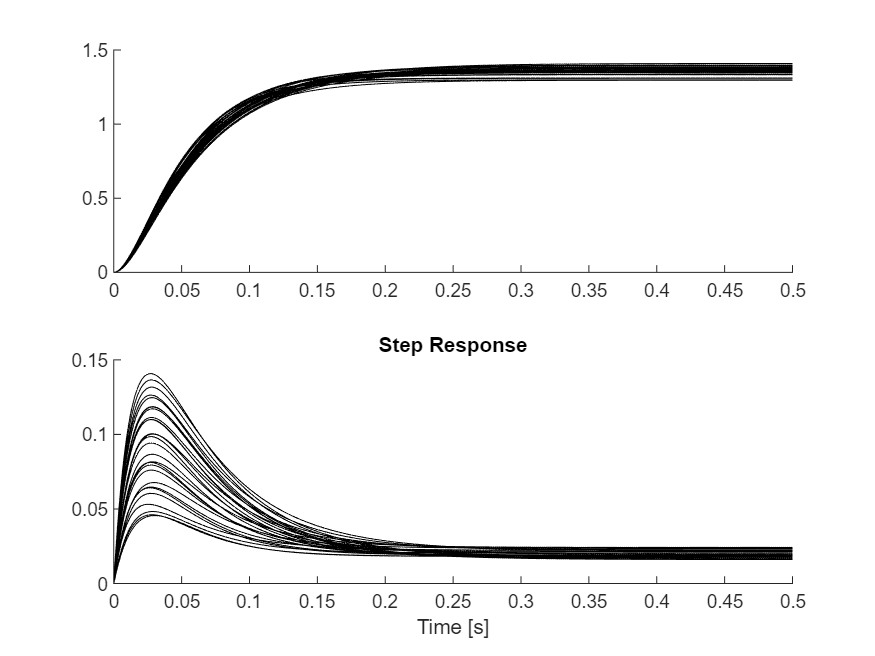


S = sys.Structure;
S.B.Free(1) = false;
S.C.Free = false;
S.D.Free = false;
S.K.Free = false;
sys.Structure = S;

opt = ssestOptions;
opt.InitialState = 'zero';

msys = cell(1, N_steps_identify);
m1 = zeros(1, N_steps_identify);
m2 = zeros(1, N_steps_identify);
m3 = zeros(1, N_steps_identify);
m4 = zeros(1, N_steps_identify);
m5 = zeros(1, N_steps_identify);

for j=1:N_steps_identify
    msys{j} = ssest(c_iddata{j}, sys, opt);

%     m1(j) = msys{j}.A(1,1);
%     m2(j) = msys{j}.A(1,2);
%     m3(j) = msys{j}.A(2,1);
%     m4(j) = msys{j}.A(2,2);
%     m5(j) = msys{j}.B(2,1);
    
%     figure; compare(c_iddata{j}, msys{j});
end

figure; 
for i=1:length(msys)
    [y, t] = step(msys{i}, 0.5);

    subplot(2,1,1);
    hold on; 
    plot(t, y(:,1), "k");
    
    subplot(2,1,2);
    hold on; 
    plot(t, y(:,2), "k");
end
title("Step Response");
xlabel("Time [s]");
hold off;

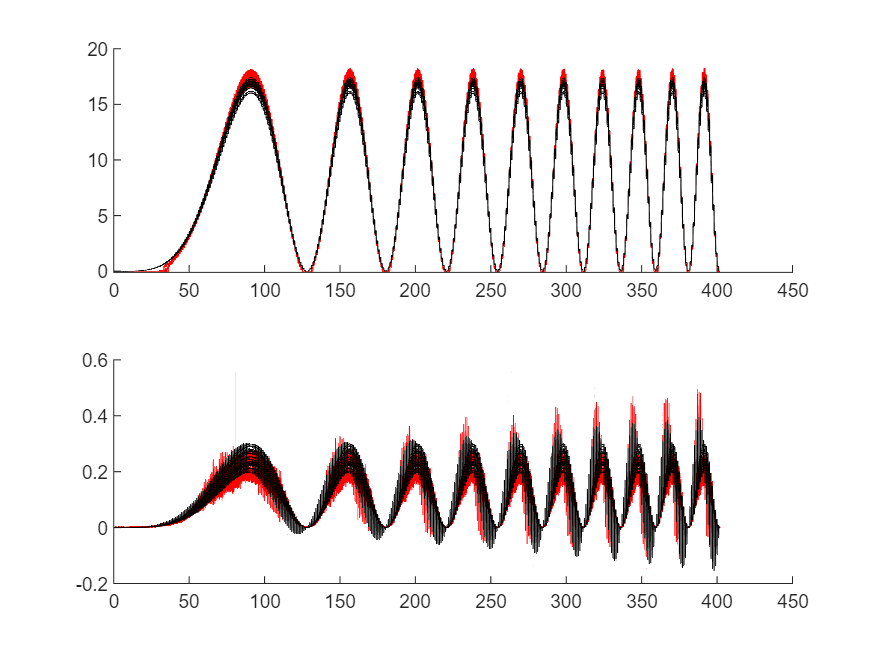

% ¿Validando los modelos con la respuesta chirp?

figure; hold on; % DEBUG

% Experimentos steps
for i=1:length(M_chirp)
    M = M_chirp{i};
    T = (M(:,1) - M(1,1)) / 1000; % quitamos el offset de tiempo de inicialización
    U = (M(:,2)/U_max) * V_nom;
    P = M(:,4); % Position [rad]
    V = M(:,5); % Velocity [rad/s]
    I = M(:,6) / 1000 - I_offset; % Current [A]

    subplot(2,1,1);
    hold on; 
    plot(T, V, "r");

    subplot(2,1,2);
    hold on; 
    plot(T, I, "r");

    for j=1:length(msys)
        [y, t] = lsim(msys{j}, U, T);
    
        subplot(2,1,1);
        hold on; 
        plot(t, y(:,1), "k");
        
        subplot(2,1,2);
        hold on; 
        plot(t, y(:,2), "k");
    end
end

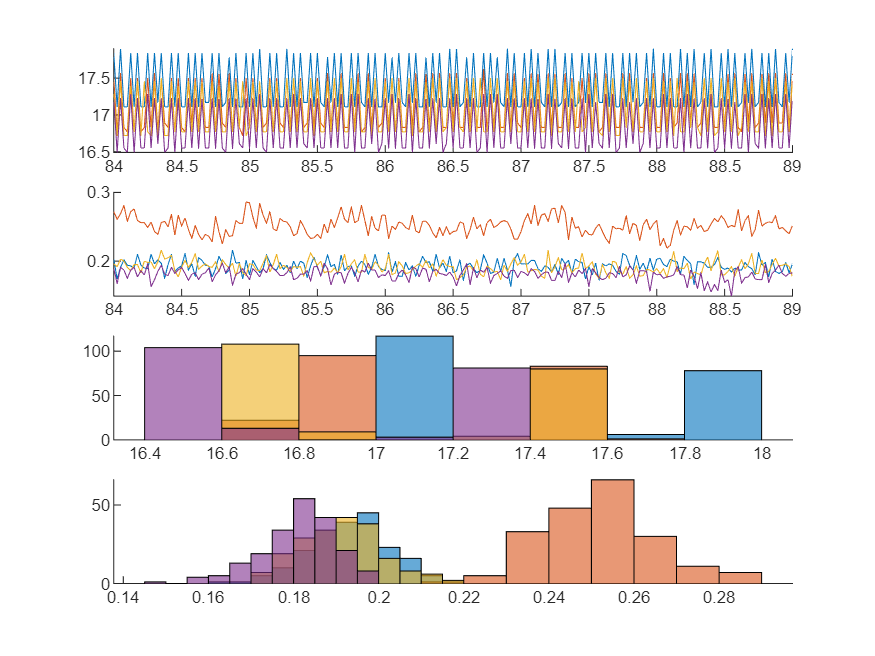

% Obteniendo la covarianza del la medida

figure; hold on;

mus = zeros(2, length(M_steps));
sigmas = zeros(2, length(M_steps));

% Experimentos steps
for i=1:length(M_steps)
    M = M_steps{i};
    T = (M(:,1) - M(1,1)) / 1000; % quitamos el offset de tiempo de inicialización
    U = (M(:,2)/U_max) * V_nom;
    P = M(:,4); % Position [rad]
    V = M(:,5); % Velocity [rad/s]
    I = M(:,6) / 1000 - I_offset; % Current [A]

    idx_in = find(T >= 84, 1);
    idx_fi = find(T >= 89, 1);

    subplot(4,1,1);
    hold on; 
    plot(T(idx_in:idx_fi), V(idx_in:idx_fi));

    subplot(4,1,2);
    hold on; 
    plot(T(idx_in:idx_fi), I(idx_in:idx_fi));

    mus(1, i) = mean(V(idx_in:idx_fi));
    mus(2, i) = mean(I(idx_in:idx_fi));

    sigmas(1, i) = std(V(idx_in:idx_fi) - mus(1, i));
    sigmas(2, i) = std(I(idx_in:idx_fi) - mus(2, i));

    subplot(4,1,3);
    hold on; 
    histogram(V(idx_in:idx_fi));

    subplot(4,1,4);
    hold on; 
    histogram(I(idx_in:idx_fi));
end


sig = max(sigmas') % Standard deviation

sig =     0.3581    0.0133


% m1_min = min(m1)
% m1_max = max(m1)
% 
% m2_min = min(m2)
% m2_max = max(m2)
% 
% m3_min = min(m3)
% m3_max = max(m3)
% 
% m4_min = min(m4)
% m4_max = max(m4)
% 
% m5_min = min(m5)
% m5_max = max(m5)
% 
% A = [m1_min m2_min; m3_min m4_min];
% B = [0; m5_min];
% sys_min = idss(A, B, C, D, 'Ts', 0);
% 
% [y, t] = step(sys_min, 0.5);
% 
% subplot(2,1,1);
% hold on; 
% plot(t, y(:,1), "r");
% 
% subplot(2,1,2);
% hold on; 
% plot(t, y(:,2), "r");
% 
% A = [m1_max m2_max; m3_max m4_max];
% B = [0; m5_max];
% sys_max = idss(A, B, C, D, 'Ts', 0);
% 
% [y, t] = step(sys_max, 0.5);
% 
% subplot(2,1,1);
% hold on; 
% plot(t, y(:,1), "b");
% 
% subplot(2,1,2);
% hold on; 
% plot(t, y(:,2), "b");

% CONCLUSIONES
% los máximos y mínimos de los valores no tienen porque ser los rangosS